# **2D Tree-shaped Structure Synthesis**

**Crust and Medial Axis Algorithms**

## **1. Point Cloud Generation**

** 1.1     **Build a custom point cloud using the Point Cloud Interface App:

% matlab.apputil.install('\path\to\Point Cloud Interface APP.mlappinstall')
% matlab.apputil.run('PointCloudInterfaceAPP')

% save variables from the PCI App as var1, var2
%x = var1;
%y = var2;

**1.2     **Already implemented shapes:

% First shape - symmetric closed curve
teta = 0: 0.5 : 90;
r = 1 + 2*(cos(teta).^2);
x = (r .* cos(teta)).';
y = (r .* sin(teta)).';

%Second shape - heart
% t = 0: 0.5 : 90;
% x = (16*(sin(t).^3)).';
% y = (13*cos(t) - 5*cos(2*t) - 2*cos(3*t) - cos(4*t)).';

%Third shape - symmetric closed curve
% t = 0: 0.5 : 90;
% x = (cos(t).^3).';
% y = (sin(t).^3).';

%Fourth shape - ellipse
% a = 10; 
% b = 5;
% t = -pi:0.05:pi;
% x = (a*cos(t)).';
% y = (b*sin(t)).';

**1.3 **Get Points from Image

%im = imread('\images\maple.png');
%P = getImagePoints(im, 1000);
%x = P(:, 1);
%y = P(:, 2);

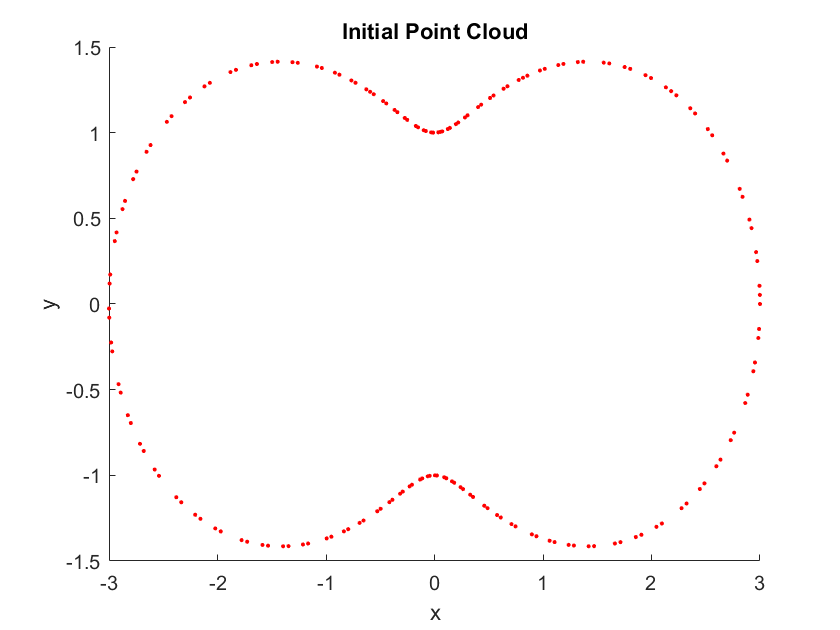

N = size(x, 1);    %number of points
plt1 = scatter(x, y, 'r.');
title('Initial Point Cloud')

xlabel('x')
ylabel('y')

## 2. Crust Algorithm and Medial Axis Approximation

**2.1     **Delaunay triangulation and Voronoi Diagram

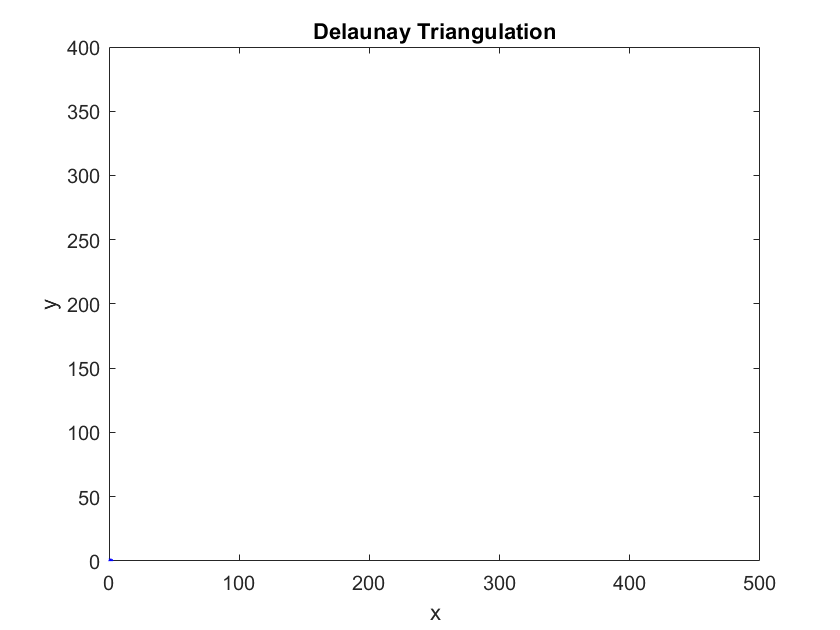

DT = delaunayTriangulation(x, y);
triplot(DT)
title('Delaunay Triangulation')
xlabel('x')
ylabel('y')

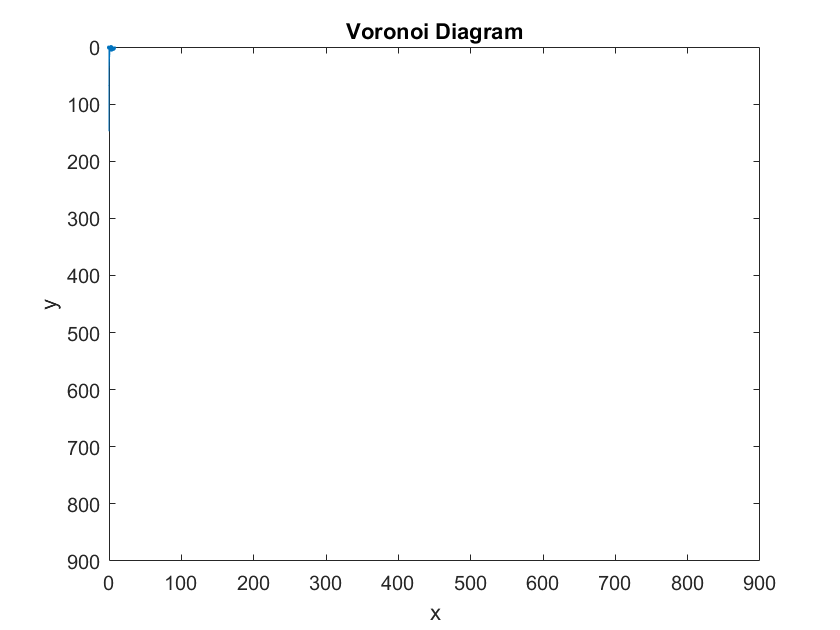

voronoi(DT)
title('Voronoi Diagram')
xlabel('x')
ylabel('y')

[V, r] = voronoiDiagram(DT); % V = list of Voronoi vertices, 
                             % r = region matrix (will be useful in filtering - 3.1)
V(1, :) = [];               %eliminate the Inf vertex

** 2.2     **Adding the Voronoi vertices to the initial point cloud

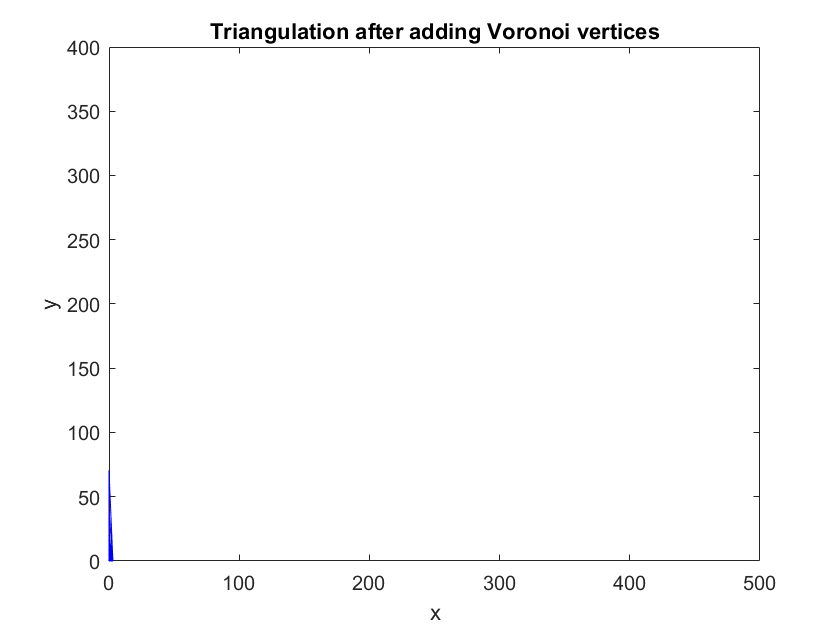

DT.Points = [DT.Points; V];
triplot(DT)     %axis depends on choice of x, y, see previous graph
title('Triangulation after adding Voronoi vertices')
xlabel('x')
ylabel('y')

**2.3     **Computation of crust edges

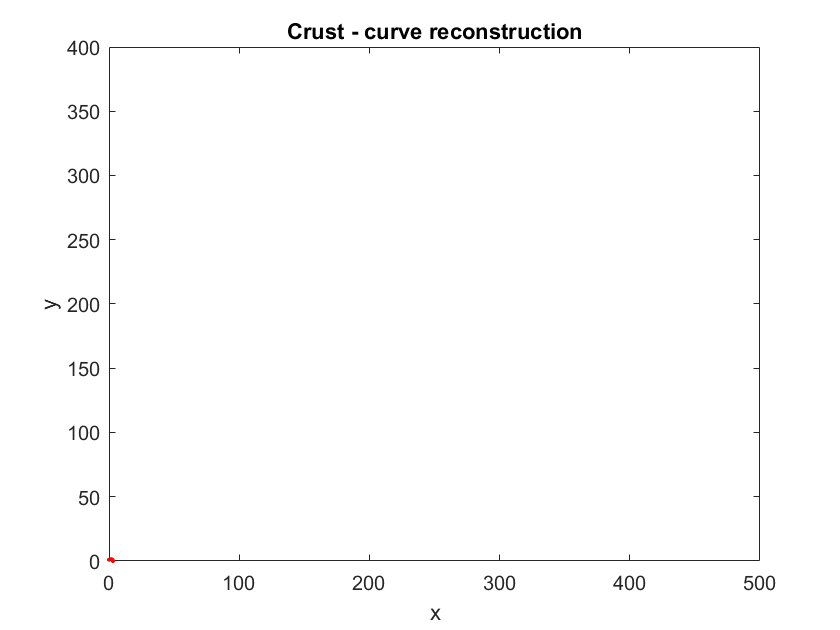

edges = DT.edges();

%the crust edges are the triangulation edges between 2 points from the
%initial point cloud (i.e. edges that are between entries <= N)
curve_edges = edges((edges(:, 1) <= N & edges(:, 2) <= N), :);  %edges for curve reconstruction
x_curve = x(curve_edges.');
y_curve = y(curve_edges.');

plot(x_curve, y_curve, 'r-')
hold on
scatter(x, y, 'r.')
title('Crust - curve reconstruction')
xlabel('x')
ylabel('y')

**2.4**     Medial axis approximation

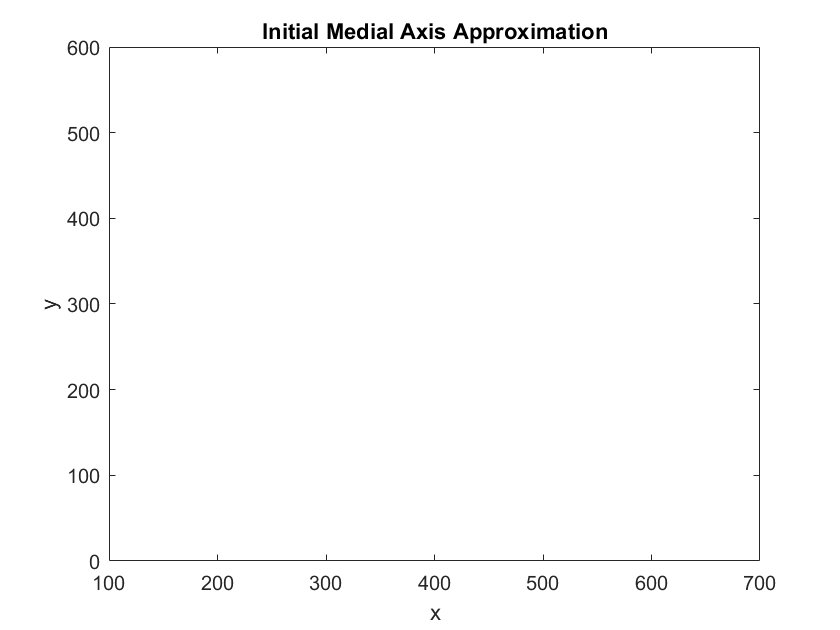

%keep edges that are only between Voronoi vertices
medial_edges = edges((edges(:, 1) > N & edges(:, 2) > N), :);  %edges for medial axis

new_x = DT.Points(:, 1);    %expended for size and point matching
new_y = DT.Points(:, 2);

x_medial = new_x(medial_edges.'); 
y_medial = new_y(medial_edges.');

plot(x_medial, y_medial, 'b-')
title('Initial Medial Axis Approximation')
hold off

## **  3. Medial Axis Point Filtering**

**3.1   **Computation of poles

% for i = 1:N
%     r{i}(1, :) =  r{i}(1, :) - 1;
%     r{i} = r{i}(r{i} ~= 0);     % eliminate 0 point, equivalent to Inf vertex
% end
% 
% VR_refined = [];    %list of poles
% 
% for i = 1:N
%     region = V(r{i}, :);        %coordinates of Voronoi points adjacent to ith region
%     vor_pts = size(region, 1);      %number of Voronoi points adjacent to ith region
%     
%     %1, 2 points adjacent => no need to compute the poles
%     if (vor_pts == 1 || vor_pts == 2)
%         VR_refined = [VR_refined; region];   
%     
%     %computing the poles
%     else
%         max = 0;
%         min = 10^19;
%         for j = 1:vor_pts
%             d = pdist([x(i, 1) y(i, 1); region(j, 1) region(j, 2)], 'euclidean');   
%             if d > max
%                 max = d;
%                 pole1 = [region(j, 1) region(j, 2)];
%             end
%         end
%         
%         for k = 1:vor_pts
%             inpr = dot([region(k, 1) region(k, 2)], pole1);
%             if inpr < min
%                 min = inpr;
%                 pole2 = [region(k, 1) region(k, 2)];
%             end
%         end
%         VR_refined = [VR_refined; pole1; pole2];
%     end
% end

**3.2     **Computation of crust and medial axis algorithm

% DT_ref = delaunayTriangulation(x, y);
% DT_ref.Points = [DT_ref.Points; VR_refined];    %add selected Voronoi points (poles) to DT
% edges_ref = DT_ref.edges();
% medial_edges_ref = edges_ref((edges_ref(:, 1) > N & edges_ref(:, 2) > N), :);   %edges for medial axis
% 
% new_x = DT_ref.Points(:, 1);   %expended for size matching later on
% new_y = DT_ref.Points(:, 2);
% 
% x_medial_ref = new_x(medial_edges_ref.'); 
% y_medial_ref = new_y(medial_edges_ref.');
% 
% plot(x_curve, y_curve, 'r-')
% hold on
% scatter(x, y, 'r.')
% xlabel('x')
% ylabel('y')
% plot(x_medial_ref, y_medial_ref, 'b-')
% axis([100 700 0 600])     %axis depends on choice of x, y, see previous graph
% title('Pole Filtering')
% hold off

## 4. Medial Axis Edge Filtering

**4.1.     **Computation of initial Voronoi edges

DT = delaunayTriangulation(x, y);   %recompute DT
C = circumcenter(DT);       %coordinates of circumcenters of all triangles in DT (ith row - ith triangle)

vor_edges = [];
Nb = neighbors(DT);     %matrix of n x 3 : n = number of triangles in triangulation; 
                        % row i = the triangles that neighbor triangle i

%vor_edges - matrix of connected points in the initial Voronoi diagram 
%columns 1, 2: x, y of point 1
%columns 3, 4: x, y of point 2

for i = 1:size(Nb, 1)
    v1 = C(i, :);
    for j = 1:size(Nb, 1)
        if ismember(j, neighbors(DT, i))
           v2 = C(j, :); 
           vor_edges = [vor_edges; v1(:, 1) v1(:, 2) v2(:, 1) v2(:, 2)]; 
        end
    end
end
% [vx, vy] = voronoi(x, y);
% 
% for i = 1:size(vx, 2)
%     vor_edges = [vor_edges; vx(1, i) vy(1, i) vx(2, i) vy(2, i)];
% end

%convert coordinates to indeces

voredges_index_one = [];
voredges_index_two = [];

for i = 1:size(vor_edges, 1)
    x1 = vor_edges(i, 1);
    y1 = vor_edges(i, 2);
    x2 = vor_edges(i, 3);
    y2 = vor_edges(i, 4);
    for j = 1:size(V, 1)
        xj = V(j, 1);
        yj = V(j, 2);
        if (xj == x1 && yj == y1)
            voredges_index_one = [voredges_index_one; j];
        end
        if (xj == x2 && yj == y2)
            voredges_index_two = [voredges_index_two; j];
        end
    end
end

%indices change when we add the Voronoi points to the point cloud
voronoi_edges = [voredges_index_one voredges_index_two] + size(DT.Points, 1);

**4.2 **    Crust and Medial Axis algorithms

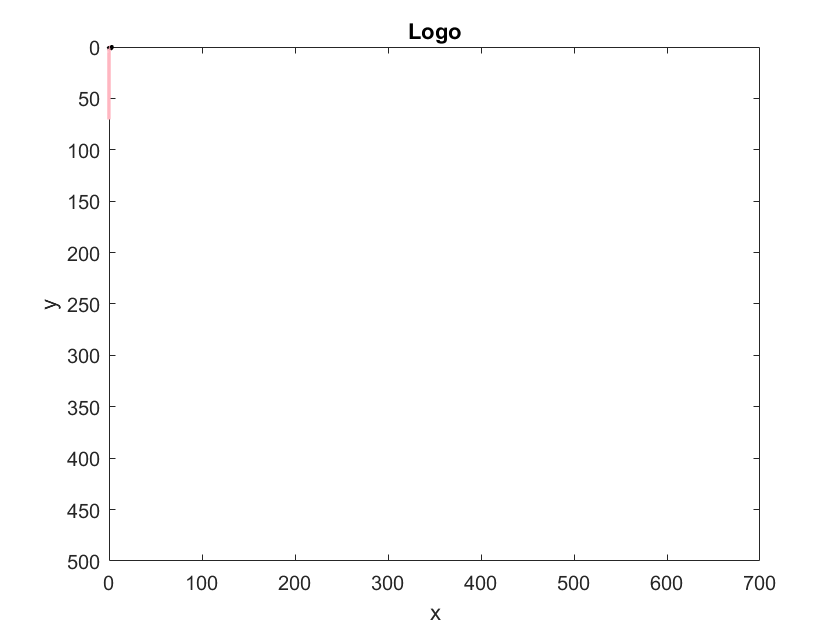

DT.Points = [DT.Points; V];
edges = DT.edges();
    
medial_edges = edges((edges(:, 1) > N & edges(:, 2) > N), :);  %edges for medial axis

final_medial = [];
for i = 1:size(medial_edges, 1)
    for j = 1:size(voronoi_edges, 1)
        if (medial_edges(i, 1) == voronoi_edges(j, 1)) && (medial_edges(i, 2) == voronoi_edges(j, 2))
            final_medial = [final_medial; medial_edges(i, 1) medial_edges(i, 2)];
        end
    end
end

new_x = DT.Points(:, 1);  
new_y = DT.Points(:, 2);

x_medial_final = new_x(final_medial.'); 
y_medial_final = new_y(final_medial.');

plot(x_curve, y_curve, 'k-', 'LineWidth', 0.8)
hold on
scatter(x, y, 'k.')
% hold on
xlabel('x')
ylabel('y')
title('Logo')
plot(x_medial_final, y_medial_final, 'Color', [255 182 193]/255, 'LineWidth', 1.7)    
set(gca, 'YDir', 'reverse')
hold off

## 5. Nested Curves - Medial Axis Iteration

% for i = 1:3
%     [x_curve, y_curve, x_medial, y_medial, new_x, new_y] = ma_iteration(x, y, N);
%     figure()
%     plot(x_medial, y_medial, 'b-')
%     hold on
%     scatter(x, y, 'r.')
%     xlabel("x")
%     ylabel("y")
%     scatter(x, y, 'r.')
%     axis([0 600 0 300]) 
%     title("Medial Axis - Iteration " + int2str(i))
%     set(gca, 'YDir', 'reverse')
%     hold off
%     x = new_x;
%     y = new_y;
%     N = size(new_x, 1);
% end

function [x_curve, y_curve, x_medial, y_medial, new_x, new_y] = ma_iteration(x, y, N)
    
    DT = delaunayTriangulation(x, y); 
    
    V = voronoiDiagram(DT);
    V(1, :) = [];
    C = circumcenter(DT);
    
    vor_edges = [];
    Nb = neighbors(DT);
    
    for i = 1:size(Nb, 1)
        v1 = C(i, :);
        for j = 1:size(Nb, 1)
            if ismember(j, neighbors(DT, i))
               v2 = C(j, :); 
               vor_edges = [vor_edges; v1(:, 1) v1(:, 2) v2(:, 1) v2(:, 2)]; 
            end
        end
    end
    
    voredges_index_one = [];
    voredges_index_two = [];
    
    for i = 1:size(vor_edges, 1)
        x1 = vor_edges(i, 1);
        y1 = vor_edges(i, 2);
        x2 = vor_edges(i, 3);
        y2 = vor_edges(i, 4);
        for j = 1:size(V, 1)
            xj = V(j, 1);
            yj = V(j, 2);
            if (xj == x1 && yj == y1)
                voredges_index_one = [voredges_index_one; j];
            end
            if (xj == x2 && yj == y2)
                voredges_index_two = [voredges_index_two; j];
            end
        end
    end
    
    voronoi_edges = [voredges_index_one voredges_index_two] + size(DT.Points, 1);
    
    DT.Points = [DT.Points; V];
    edges = DT.edges();
    
    curve_edges = edges((edges(:, 1) <= N & edges(:, 2) <= N), :);  %edges for curve reconstruction
    medial_edges = edges((edges(:, 1) > N & edges(:, 2) > N), :);  %edges for medial axis
    
    final_medial = [];
    for i = 1:size(medial_edges, 1)
        for j = 1:size(voronoi_edges, 1)
            if (medial_edges(i, 1) == voronoi_edges(j, 1)) && (medial_edges(i, 2) == voronoi_edges(j, 2))
                final_medial = [final_medial; medial_edges(i, 1) medial_edges(i, 2)];
            end
        end
    end
    
    x_curve = x(curve_edges.');
    y_curve = y(curve_edges.');
    
    new_x = DT.Points(:, 1);   %expended for size matching later on
    new_y = DT.Points(:, 2);
    
    x_medial = new_x(final_medial.'); 
    y_medial = new_y(final_medial.');
    
end

function P = getImagePoints(image, n)
    P = zeros(2, n);
    
    imshow(image);    
    k = 0;
    hold on;     
    
    while 1
        [xi, yi, but] = ginput(1); 
        if ~isequal(but, 1)     
            break
        end
        
        k = k + 1;
        P(1, k) = xi;
        P(2, k) = yi;

        plot(xi, yi, 'yo');

        if isequal(k, n)
            break
        end
    end
    
    hold off;
    if k < size(P, 2)
        P = P(:, 1:k);
    end
end